# Test TR direct moment solvers accuracy and speed

Tests NIRFAST available sparse linear problems solvers:

- GPU - GPU (CUDA) parallel implementation of the BiCGStab (preconditioned with FSAI)

- \ - MATLAB backslash, LU decomposition for symmetrical problems

Uses a slab (120x120x50mm) mesh with a coarse element size (~1.85mm^3) to test solvers:

- speed

- accuracy against moments calculated from TR curves

The test mesh is available as ‘slab_stnd’ mesh. But use any mesh. Solvers tolerances set to the default values

close all
clear variables
clc

## display properties

set(0, 'DefaultAxesFontname', 'Arial CE');
font_size = 16;
set(0, 'DefaultAxesFontsize', font_size);
set(0, 'defaulttextfontname', 'Arial CE');
set(0, 'defaulttextfontsize', font_size);
set(0, 'defaultfigurecolor', 'w')

## calculate moments directly with all available solvers

% mesh = load_mesh('cylinder_stnd');
mesh = load_mesh('slab_stnd');

Sources integration functions loaded
Detectors integration functions loaded


mesh.mua = ones(size(mesh.mua))*0.01;
mesh.mus = ones(size(mesh.mus))*1;

% test up to 2nd moment order (0th, 1st, and 2nd)
max_order = 2;

% GPU
timeStart = tic;
[data_GPU] = femdata_stnd_TR_moments(mesh,max_order,'field',[],solver_name_GPU);
time_execution(1) = toc(timeStart);

% CPU and MATLAB 'bicgstab'
% not implemented yet

% backslash
timeStart = tic;
[data_backslash] = femdata_stnd_TR_moments(mesh,max_order,'field',[],solver_name_backslash);
time_execution(2) = toc(timeStart);

## calculate moments from time-resolved curves

% variable time sampling, 128 points, up to ~4 times mean time of flight
% please check curves if the calculated moments looks wrong
timeStart = tic;
data_TR = femdata_TR(mesh,[],[],128,4);
for ind_rsd = 1:size(data_TR.tpsf,1)
    data_TR.moments(ind_rsd,:) = DTOF_stat_moments([data_TR.time(ind_rsd,:)' data_TR.tpsf(ind_rsd,:)'],'non-central');
end
time_execution(3) = toc(timeStart);

## plot exec time

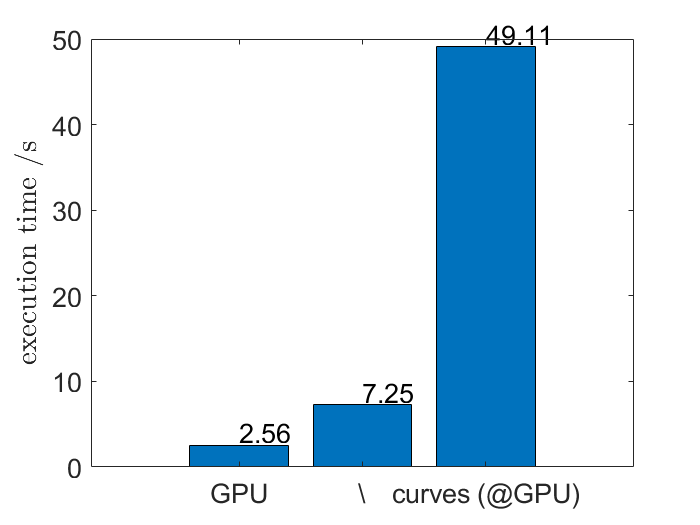

figure('Name',mesh.name)
labels = {'GPU','\','curves (@GPU)'};
bar(time_execution)
hold on
for ind_exec = 1:length(time_execution)
    text(ind_exec,time_execution(ind_exec)+0.03*max(time_execution),num2str(time_execution(ind_exec),'%4.2f'))
end
hold off
set(gca,'XTickLabel',labels)
ylabel('execution time /s','Interpreter','latex','FontSize',22)

## plot calculated moments

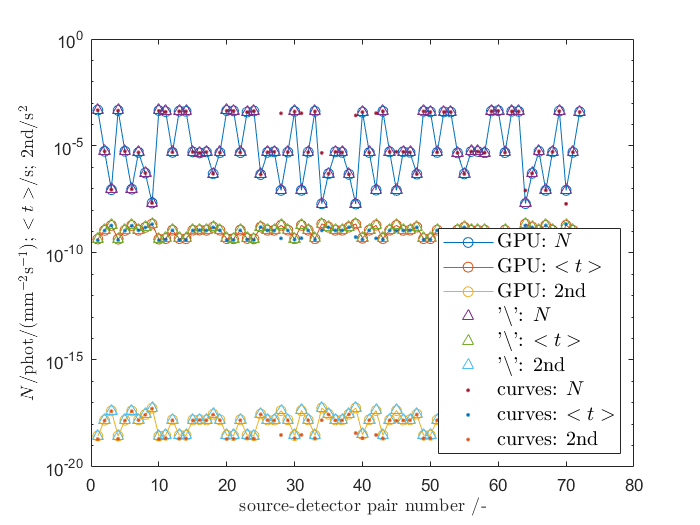

figure('Name',mesh.name)
semilogy(data_GPU.moments,'o-')
hold on
semilogy(data_backslash.moments,'^')
semilogy(data_TR.moments(:,1:3),'.')
xlabel('source-detector pair number /-','Interpreter','latex','FontSize',22)
ylabel('$N$/phot$/($mm$^{-2}$s$^{-1})$;  $<t>$/s;  2nd/s$^{2}$','Interpreter','latex','FontSize',22)
legend({'GPU: $N$','GPU: $<t>$','GPU: 2nd',...
        '''\textbackslash'': $N$','''\textbackslash'': $<t>$','''\textbackslash'': 2nd',...
        'curves: $N$','curves: $<t>$','curves: 2nd'},'interpreter','latex','FontSize',12,'Location','southeast')

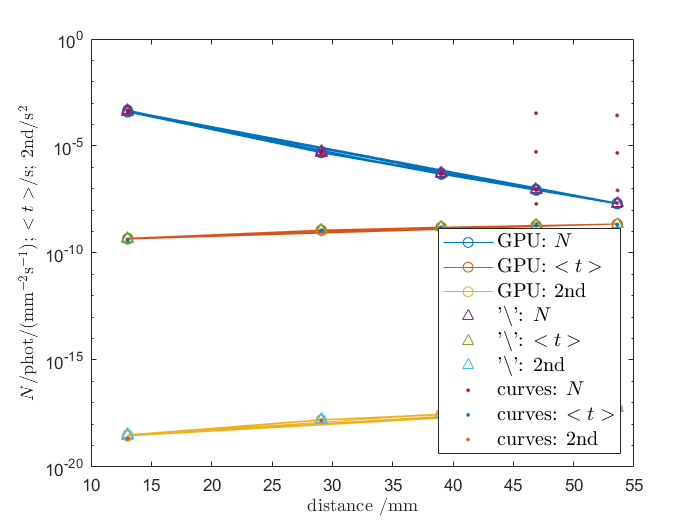


% all source-detector distances
dist = sqrt(sum((mesh.source.coord(mesh.link(:,1),:) - mesh.meas.coord(mesh.link(:,2),:)).^2,2));
    
figure()
semilogy(dist,data_GPU.moments,'o-')
hold on
semilogy(dist,data_backslash.moments,'^')
semilogy(dist,data_TR.moments(:,1:3),'.')
xlabel('distance /mm','Interpreter','latex','FontSize',22)
ylabel('$N$/phot$/($mm$^{-2}$s$^{-1})$;  $<t>$/s;  2nd/s$^{2}$','Interpreter','latex','FontSize',22)
legend({'GPU: $N$','GPU: $<t>$','GPU: 2nd',...
        '''\textbackslash'': $N$','''\textbackslash'': $<t>$','''\textbackslash'': 2nd',...
        'curves: $N$','curves: $<t>$','curves: 2nd'},'interpreter','latex','FontSize',12,'Location','southeast')

## plot accuracy of solvers

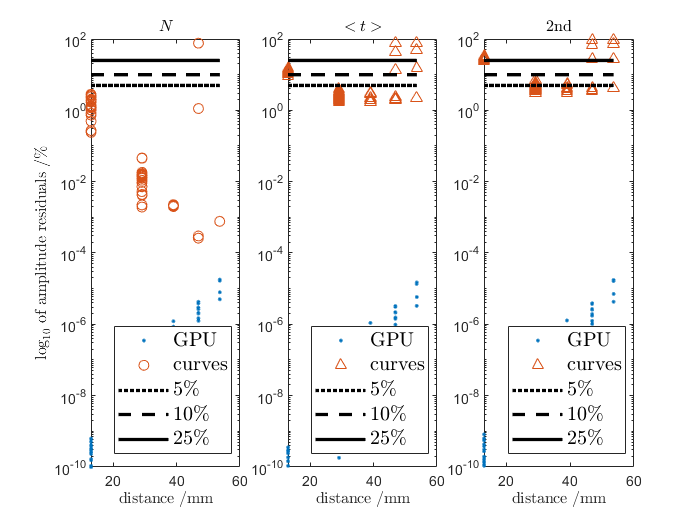

% relate to backslash
residuals_GPU = (data_GPU.moments - data_backslash.moments)./data_backslash.moments*100;
residuals_curves = (data_TR.moments - data_backslash.moments)./data_backslash.moments*100;

figure()
subplot(1,3,1)
plot(dist,abs(residuals_GPU(:,1)),'.')
hold on
plot(dist,abs(residuals_curves(:,1)),'o')
plot([min(dist) max(dist)], [5 5],':k','LineWidth',2)
plot([min(dist) max(dist)], [10 10],'--k','LineWidth',2)
plot([min(dist) max(dist)], [25 25],'-k','LineWidth',2)
ylim([1e-10 1e2])
set(gca,'YScale','log')
title('$N$','Interpreter','latex','FontSize',22)
xlabel('distance /mm','Interpreter','latex','FontSize',22)
ylabel('$\log_{10}$ of amplitude residuals /\%','Interpreter','latex','FontSize',22)
legend({'GPU','curves','5\%','10\%','25\%'},'Interpreter','latex','FontSize',12,'Location','southeast')

subplot(1,3,2)
plot(dist,abs(residuals_GPU(:,2)),'.')
hold on
plot(dist,abs(residuals_curves(:,2)),'^')
plot([min(dist) max(dist)], [5 5],':k','LineWidth',2)
plot([min(dist) max(dist)], [10 10],'--k','LineWidth',2)
plot([min(dist) max(dist)], [25 25],'-k','LineWidth',2)
ylim([1e-10 1e2])
set(gca,'YScale','log')
title('$<t>$','Interpreter','latex','FontSize',22)
xlabel('distance /mm','Interpreter','latex','FontSize',22)
legend({'GPU','curves','5\%','10\%','25\%'},'Interpreter','latex','FontSize',12,'Location','southeast')

subplot(1,3,3)
plot(dist,abs(residuals_GPU(:,3)),'.')
hold on
plot(dist,abs(residuals_curves(:,3)),'^')
plot([min(dist) max(dist)], [5 5],':k','LineWidth',2)
plot([min(dist) max(dist)], [10 10],'--k','LineWidth',2)
plot([min(dist) max(dist)], [25 25],'-k','LineWidth',2)
ylim([1e-10 1e2])
set(gca,'YScale','log')
title('2nd','Interpreter','latex','FontSize',22)
xlabel('distance /mm','Interpreter','latex','FontSize',22)
legend({'GPU','curves','5\%','10\%','25\%'},'Interpreter','latex','FontSize',12,'Location','southeast')

## plot 3D moment fields

% which source we want to observe
source_no = 7;

% N
plotimage(mesh,log10(abs(squeeze(data_GPU.phi(:,source_no,1)))))

ans =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [374302×4 double]
     Vertices: [65959×3 double]

  Show all properties


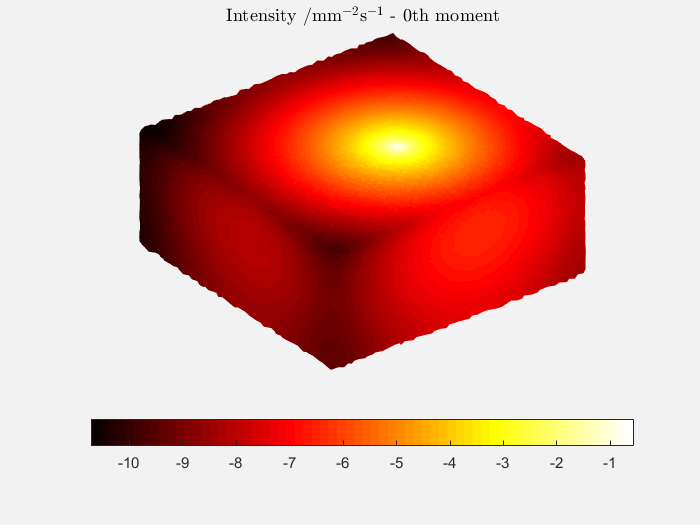

title('Intensity /mm$^{-2}$s$^{-1}$ - 0th moment','Interpreter','latex')

%<t>
plotimage(mesh,(abs(squeeze(data_GPU.phi(:,source_no,2)))))

ans =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [374302×4 double]
     Vertices: [65959×3 double]

  Show all properties


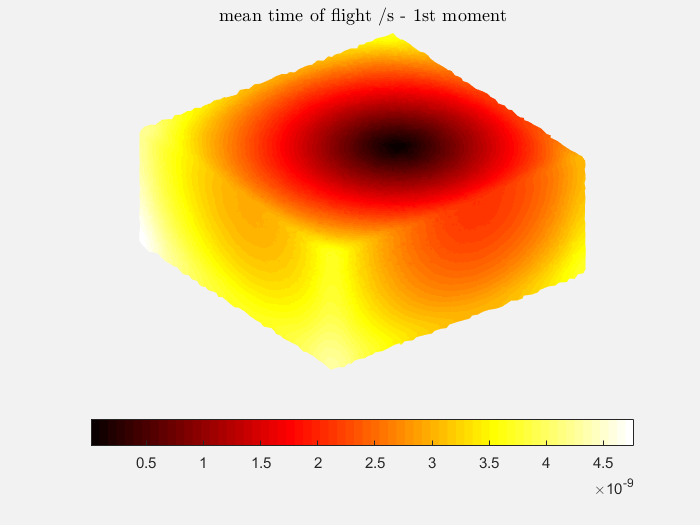

title('mean time of flight /s - 1st moment','Interpreter','latex')

%V
plotimage(mesh,(abs(squeeze(data_GPU.phi(:,source_no,3)))))

ans =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [374302×4 double]
     Vertices: [65959×3 double]

  Show all properties


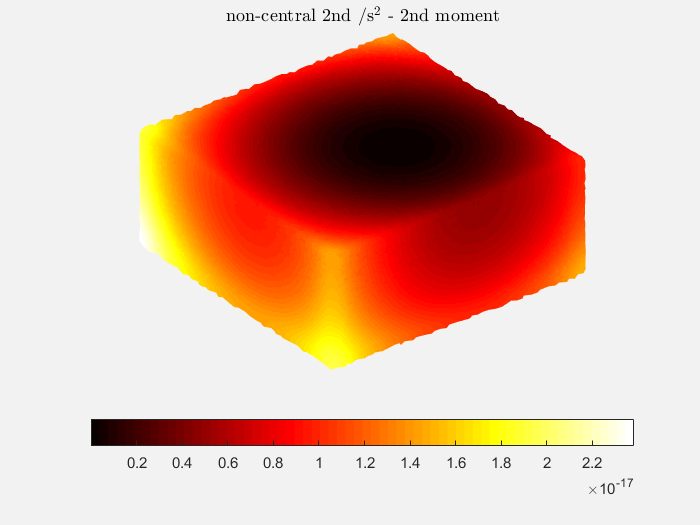

title('non-central 2nd /s$^{2}$ - 2nd moment','Interpreter','latex')